# Feature Analysis

data = readtable("train_desc.csv");

## Preprocess

## NCA

X = data(:,1:(end-1));
%X = table2array(X);
Y = data(:,end);
mdl = fscnca(X,Y);

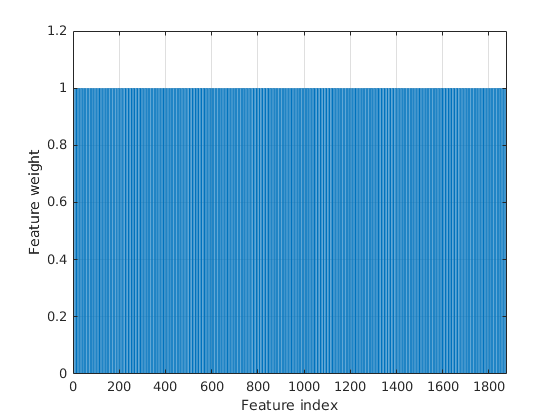

% varNames = string(data.Properties.VariableNames(1:(end-2)));
% varNames = strrep(varNames, '_', ' ');
% labels = categorical(varNames);
% bar(labels, mdl.FeatureWeights)
bar(mdl.FeatureWeights)

grid on
xlabel('Feature index')
ylabel('Feature weight')

nca = mdl;
tol    = 0.02;
selidx = find(nca.FeatureWeights > tol*max(1,max(nca.FeatureWeights)))

selidx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10



dataRel = data(:,selidx);